clear all; close all; clc;

J1 = 0.0025;         %kgm^2
J2 = 0.0018;         %kgm^2
J3 = 0.0018;         %kgm^2
k1 = 2.7;            %Nm/rad
k2 = 2.6;            %Nm/rad
b1 = 0.0029;         %Nms/rad
b2 = 0.0002;         %Nms/rad
b3 = 0.00015;        %Nms/rad

A = [   0      1       0         0     0     0;
     -k1/J1 -b1/J1   k1/J1       0     0     0;
        0      0       0         1     0     0;
      k1/J2    0  -(k1+k2)/J2 -b2/J2 k2/J2   0;
        0      0       0         0     0     1;
        0      0     k2/J3       0  -k2/J3 -b3/J3];

B = [ 0  ;
     1/J1;
      0  ;
      0  ;
      0  ;
      0  ];

Ex = [  0  ;
      -1/J1;
        0  ;
        0  ;
        0  ;
        0  ];

C = [0 0 0 0 1 0];

D = zeros(1,1);

Ey = zeros(1,1);

%-------------------------------------------------Q9-------------------------------------------------------
s = tf('s');
% determining G and Gd from matrices
G = minreal(C*inv(s*eye(size(A,1)) - A)*B + D);
Gd = minreal(C*inv(s*eye(size(A,1)) - A)*Ex + Ey);

% low pass filter design
M = 2;
wb = 2.1;
A_ = 0.01;
WS = (s/M+wb)/(s+wb*A_);
WS = WS^3;

% high pass filter
M = 7;
wb = 7;
A_ = 0.07;
WKS = (s+wb/M)/(A_*s+wb);
WKS = WKS^2;

%for visualization min and max range of logspace
log_min = -2;
log_max = 3;

A = A;
B2 = B;
B1 = zeros(6,2);
C2 = -C;
C1 = [-WS*C; zeros(1,6)];
D11 = [WS -WS*Gd; 0 0];
D12 = [0; WKS];
D21 = [1 -Gd];
D22 = 0;

PA = [A B1 B2;
       C1 D11 D12;
       C2 D21 D22];

%Assumptions
if (rank(ctrb(A,B2))==size(A,1))
    disp("System is controllable -> stabilizable as well.")
end

System is controllable -> stabilizable as well.


if (rank(obsv(A,C2))==size(A,1))
    disp("System is observable -> detectable as well.")
end

System is observable -> detectable as well.



%just checked them
D12;
D21;
disp("D12 has full rank")

D12 has full rank


disp("D21 has full rank")

D21 has full rank


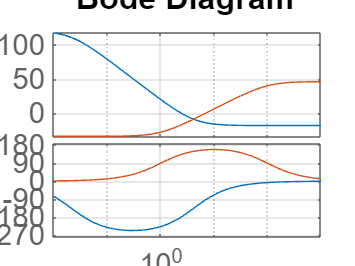


[A-s*eye(size(A)) B2; C1 D12];
[A-s*eye(size(A)) B1; C2 D21];

D11;
D22;

P = [ WS -WS*Gd -WS*G ;
      0     0    WKS  ;
      1    -Gd   -G   ];

%controller design
[K_inf, CL, Gam, ~] = mixsyn(G, WS, WKS, []);
%We want to stray away from the optimal solutino
[K_inf, CL, Gam, ~] = mixsyn(G, WS, WKS, [], [Gam*1.02 Gam*1.02]);

% S, SK and T
S = 1/(1+K_inf*G);
SK = S*K_inf;
T = K_inf*G*S;

% Two weight functions applied to S and SK
figure(1)
bode(WS, logspace(log_min, log_max, 50)); hold on;
bode(WKS, logspace(log_min, log_max, 50)); hold off;
grid on;

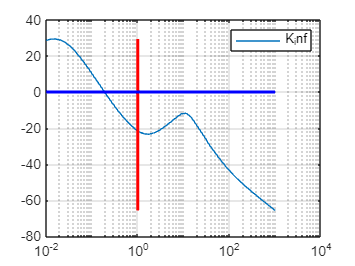

clf;

[mag, phase, omega] = bode(K_inf, logspace(log_min, log_max, 50));
mag = squeeze(mag);  % Convert magnitude matrix to a vector
omega = squeeze(omega);  % Convert omega matrix to a vector

% Controller bode (high gain at low frequencies)
figure(2);
semilogx(omega, 20*log10(mag)); hold on;
plot([1 1], [min(20*log10(mag)) max(20*log10(mag))], 'r', 'LineWidth', 2); hold on;
plot([min(omega) max(omega)], [0 0], 'b', 'LineWidth', 2); hold off;
legend({"K_inf"});
grid on;

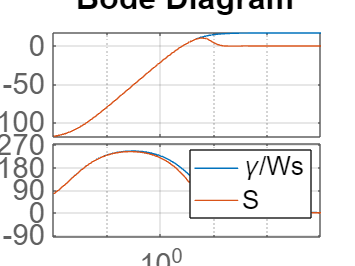

clf;

%Sensitivity function is always below gamma/WS
figure(3);
bode(Gam/WS, logspace(log_min, log_max, 50)); hold on;
bode(S, logspace(log_min, log_max, 50)); hold off;
legend({"\gamma/Ws", "S"});
grid on;

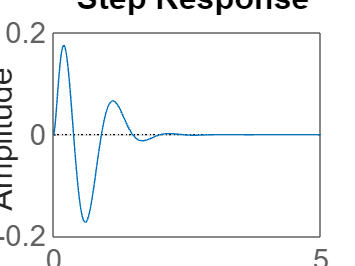

clf;

% Contorl signal
figure(4);
step(SK, 5);
grid on;

clf;

% Gamma is below 1 and not optimal
Gam

Gam = 0.8909

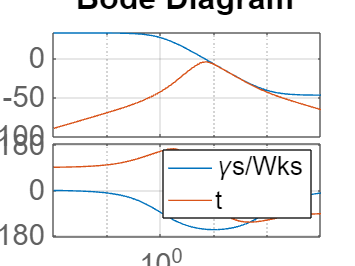


% KS is always below Gam/WKS
figure(5);
bode(Gam/WKS, logspace(log_min, log_max, 50)); hold on;
bode(SK, logspace(log_min, log_max, 50)); hold off;
legend({"\gammas/Wks", "t"});
grid on;

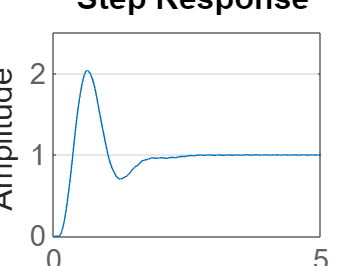

clf;

% step response (response time shall be under 2 sec)
figure(6);
step(T, 5);
grid on;

clf;

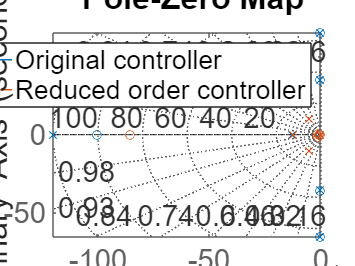

%-------------------------------------------------Q10------------------------------------------------------

Kred = reduce(K_inf, 6);
%manual DK iteration??

%pole-zero map of the two controllers
figure(7);
pzmap(K_inf); hold on;
pzmap(Kred); hold off;
legend({"Original controller", "Reduced order controller"});
grid on;

clf;

%Stability analysis
S_red = 1/(1+Kred*G);
SK_red = S_red*Kred;
T_red = Kred*G*S_red;

if (all(real(pole(T_red)) < 0))
    disp("Closed loop is stable because all poles are on the LFT")
end

Closed loop is stable because all poles are on the LFT


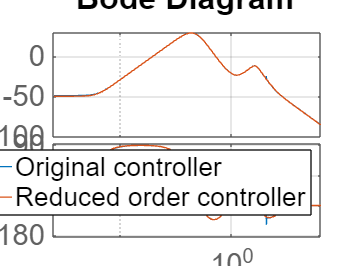


%difference between the two controllers
figure(9);
bode(K_inf, logspace(log_min, log_max, 50)); hold on;
bode(Kred, logspace(log_min, log_max, 50)); hold off;
legend({"Original controller", "Reduced order controller"});
grid on;

clf;

%-------------------------------------------------Q11------------------------------------------------------
[K_2, CL, Gam_2, ~] = mixsyn(G, WS, WKS, [], [100, 100]);
Gam_2

Gam_2 = 1.4778

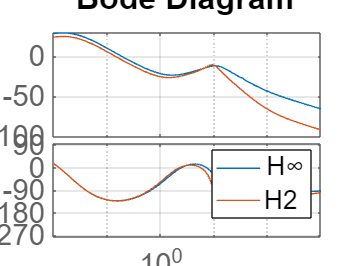


S_2 = 1/(1+K_2*G);
SK_2 = S_2*K_2;
T_2 = K_2*G*S_2;

%H_inf and H_2 controller
figure(10);
bode(K_inf, logspace(log_min, log_max, 100)); hold on;
bode(K_2, logspace(log_min, log_max, 100)); hold off;
legend({"H{\infty}", "H2"});
grid on;

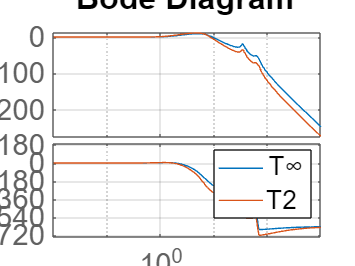

clf;

%T and T_2 closed loop tfs
figure(11);
bode(T, logspace(log_min, log_max, 100)); hold on;
bode(T_2, logspace(log_min, log_max, 100)); hold off;
legend({"T{\infty}", "T2"});
grid on;

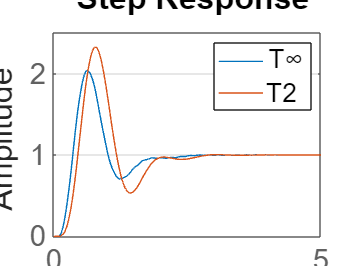

clf;

%+ step function
figure(12);
step(T, 5); hold on;
step(T_2, 5); hold off;
legend({"T{\infty}", "T2"});
grid on;

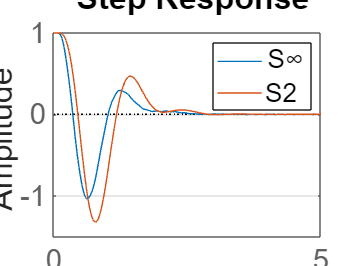

clf;

%+ control input
figure(12);
step(S, 5); hold on;
step(S_2, 5); hold off;
legend({"S{\infty}", "S2"});
grid on;

clf;